clear all
x = linspace(0,7,11)

x =          0    0.7000    1.4000    2.1000    2.8000    3.5000    4.2000    4.9000    5.6000    6.3000    7.0000


y = linspace(0,4.5,11)

y =          0    0.4500    0.9000    1.3500    1.8000    2.2500    2.7000    3.1500    3.6000    4.0500    4.5000


%Initialize variables for robot
rx = x'

rx =          0
    0.7000
    1.4000
    2.1000
    2.8000
    3.5000
    4.2000
    4.9000
    5.6000
    6.3000


ry =y'

ry =          0
    0.4500
    0.9000
    1.3500
    1.8000
    2.2500
    2.7000
    3.1500
    3.6000
    4.0500


begin = 1

begin = 1

rz = zeros(11, 1);

%Set runtime
u = linspace(0, 10,11)'

u =      0
     1
     2
     3
     4
     5
     6
     7
     8
     9


size(u)

ans =     11     1


d = 0.254;

%create matrix of velocities
r= [rx, ry, rz]

r =          0         0         0
    0.7000    0.4500         0
    1.4000    0.9000         0
    2.1000    1.3500         0
    2.8000    1.8000         0
    3.5000    2.2500         0
    4.2000    2.7000         0
    4.9000    3.1500         0
    5.6000    3.6000         0
    6.3000    4.0500         0


v = diff(r)./diff(u)

v =     0.7000    0.4500         0
    0.7000    0.4500         0
    0.7000    0.4500         0
    0.7000    0.4500         0
    0.7000    0.4500         0
    0.7000    0.4500         0
    0.7000    0.4500         0
    0.7000    0.4500         0
    0.7000    0.4500         0
    0.7000    0.4500         0


v_mag = sqrt(sum(v.^2, 2))

v_mag =     0.8322
    0.8322
    0.8322
    0.8322
    0.8322
    0.8322
    0.8322
    0.8322
    0.8322
    0.8322


tHat = v./v_mag

tHat =     0.8412    0.5408         0
    0.8412    0.5408         0
    0.8412    0.5408         0
    0.8412    0.5408         0
    0.8412    0.5408         0
    0.8412    0.5408         0
    0.8412    0.5408         0
    0.8412    0.5408         0
    0.8412    0.5408         0
    0.8412    0.5408         0


nHat = diff(tHat)./diff(u(1:end-1))

nHat =    1.0e-15 *

         0         0         0
         0   -0.1110         0
         0    0.2220         0
    0.1110   -0.3331         0
   -0.1110    0.2220         0
    0.2220   -0.4441         0
   -0.5551    0.8882         0
    0.5551   -0.8882         0
   -0.2220    0.4441         0


omega = cross(tHat(1:end-1,:), nHat)

omega =    1.0e-14 *

         0         0         0
         0         0   -0.0093
         0         0    0.0187
         0         0   -0.0340
         0         0    0.0247
         0         0   -0.0494
         0         0    0.1047
         0         0   -0.1047
         0         0    0.0494


omega = omega(:,3)

omega =    1.0e-14 *

         0
   -0.0093
    0.0187
   -0.0340
    0.0247
   -0.0494
    0.1047
   -0.1047
    0.0494




vR = v_mag(1:end-1,:) + omega*(d/2) 

vR =     0.8322
    0.8322
    0.8322
    0.8322
    0.8322
    0.8322
    0.8322
    0.8322
    0.8322


vR = vR(begin:end,:)

vR =     0.8322
    0.8322
    0.8322
    0.8322
    0.8322
    0.8322
    0.8322
    0.8322
    0.8322


vL = v_mag(1:end-1,:) - omega*(d/2)

vL =     0.8322
    0.8322
    0.8322
    0.8322
    0.8322
    0.8322
    0.8322
    0.8322
    0.8322


vL = vL(begin:end,:)

vL =     0.8322
    0.8322
    0.8322
    0.8322
    0.8322
    0.8322
    0.8322
    0.8322
    0.8322


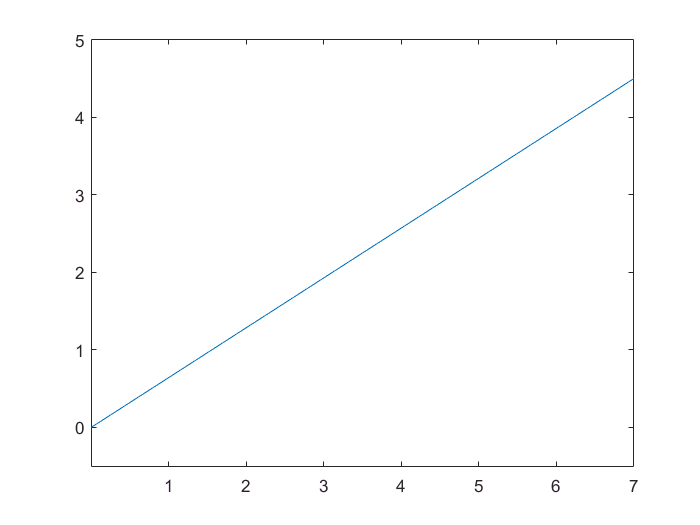

pub = rospublisher('/raw_vel');
sub_bump = rossubscriber('/bump');
plot(rx, ry)
axis('equal')

msg = rosmessage(pub);

for t = 1:5
    msg.Data = [-.1 , .1 ];
    send(pub,msg)
    pause(.1)
end
size(vL)

ans =      9     1


for t = 1:9
    msg.Data = [vL(t)*0.3 , vR(t)*0.3 ];
    send(pub,msg)
    pause(1)
 
    % wait for the next bump message
    bumpMessage = receive(sub_bump);
    % check if any of the bump sensors are set to 1 (meaning triggered)
    if any(bumpMessage.Data)
        msg.Data = [0.0, 0.0];
        send(pub, msg);
        break;
    end
    
end 
while 1
    bumpMessage = receive(sub_bump);
    % check if any of the bump sensors are set to 1 (meaning triggered)
    if any(bumpMessage.Data)
        msg.Data = [0.0, 0.0];
        send(pub, msg);
        break;
    end
end




